# GW1 Introduction

## **You must submit this worksheet before the end of the practical class**. Even if it is incomplete **IT MUST BE SUBMITTED**.

Welcome to your first MXB161 Group Worksheet (GW1).  This worksheet will draw upon the material from your first Individual Worksheet (IW1).

Download the practical material from Canvas and unzip it into a folder of your choice.  **Make that folder your Current Folder in MATLAB. **

Make sure you have the following files in your Current Folder: 

- MXB161_topic1_group.mlx (this worksheet)

- minMaxDistance.m 

- minTotalDistance.m

## 1.0 [ONLINE ONLY] Get set up online

Students on-campus, go directly to 1.1.

Once you've reached the point where all group members are present in the Zoom meeting, we need to confirm that everyone can share audio and video successfully.  If you haven't already, enable your audio and video using the Zoom tools shown , and confirm you can hear and see one another.  If there are any problems, in that good collaborative spirit, perhaps you can work together to sort it out.  Typing in the Zoom chat window should be reliable, so you can use that as your troubleshooting channel amongst yourselves.  If necessary, you can always signal to your tutor by sending a Zoom chat message if needed.

If you can all see and hear one another, congratulations!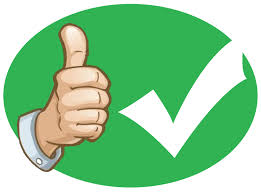

### Keyboard Duty

Now somebody needs to take charge for today.  Who will volunteer for the noble role of **keyboard duty**?

Whoever volunteers for this role will edit the master copy of this worksheet, and share the screen so that everyone can see.

Decide amongst yourselves now who will have keyboard duty for today.  Of course, this role should be rotated amongst the group members each week.

Once you've made your decision, the brave and noble person on keyboard duty should click the Share Screen tool in Zoom   so that everyone in the group can see the same copy of this worksheet.

Make a note in the box below of who is on keyboard duty for today:

## 1.1 [EVERYONE] Get to know your group

Say hi to your group members! Introduce yourselves, if you haven't done so already :) . In the box below, everyone write your name, course (and major if applicable), and a sentence about what you hope or expect to get from this unit.

Now it's time to take a group photo!  The method differs depending on whether you're taking this class on-campus or online.

#### **[ON-CAMPUS]**

Run the following MATLAB command (i.e. click Run Section or type Ctrl+Enter):

cam = webcam

'webcam' requires one of the following:
  MATLAB Support Package for BeagleBone Black Hardware
  MATLAB Coder Support Package for NVIDIA Jetson and NVIDIA DRIVE Platforms
  MATLAB Support Package for Raspberry Pi Hardware
  MATLAB Support Package for USB Webcams

The command may have no noticeable effect, but it will initialise the computer's webcam and create a handle to it called `cam`.  Now arrange yourselves in front of the webcam, smile, and run the following commands:

img = snapshot(cam);

Unrecognized function or variable 'cam'.

imshow(img)

It may take a few attempts to get a photo you're all happy with.  Rerun the previous section as often as you need.

When you're happy with your photo, click the little arrow in the top right to open a dedicated Figure window.  Use the Insert menu in the Figure window to add your names (i.e. ``tag'' yourselves) using Text, Arrows, or whatever you like).  Here's a silly example:

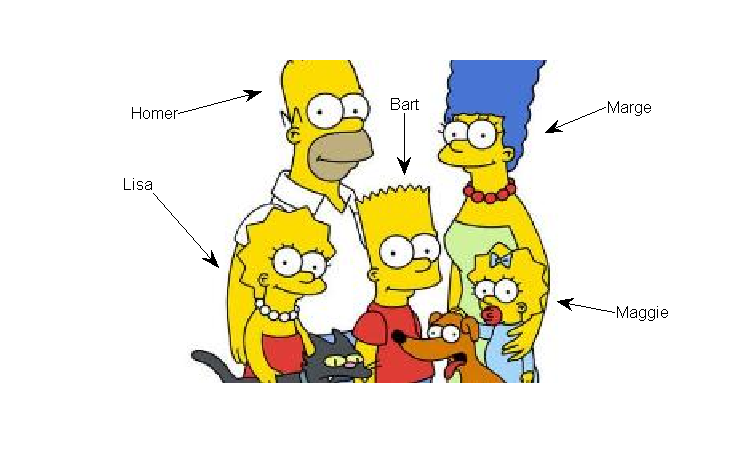

Save the figure in PNG format using File, Save As.

#### [ONLINE]

The honourable group member on keyboard duty, take a screenshot of the Zoom window.  Something like this:

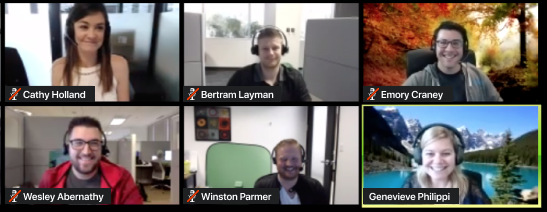

[Source: [https://zoom.us/about](https://zoom.us/about)]

Once you have the group photo saved, insert the photo into this worksheet by using the Insert menu on the MATLAB toolstrip and choose Image.  You can replace the generic Zoom photo above with your own.

#### [EVERYONE]

Now it's time to set up your MXB161 Canvas group site.

- Go to the MXB161 Canvas site, and find your group link in the Groups menu on the left of screen. Your group should be called something like MXB161_PR2_Group_XX.

- Head to the pages navigation and create a new page for your group.

- Make sure you add your group photo to the page, and give yourself a name.

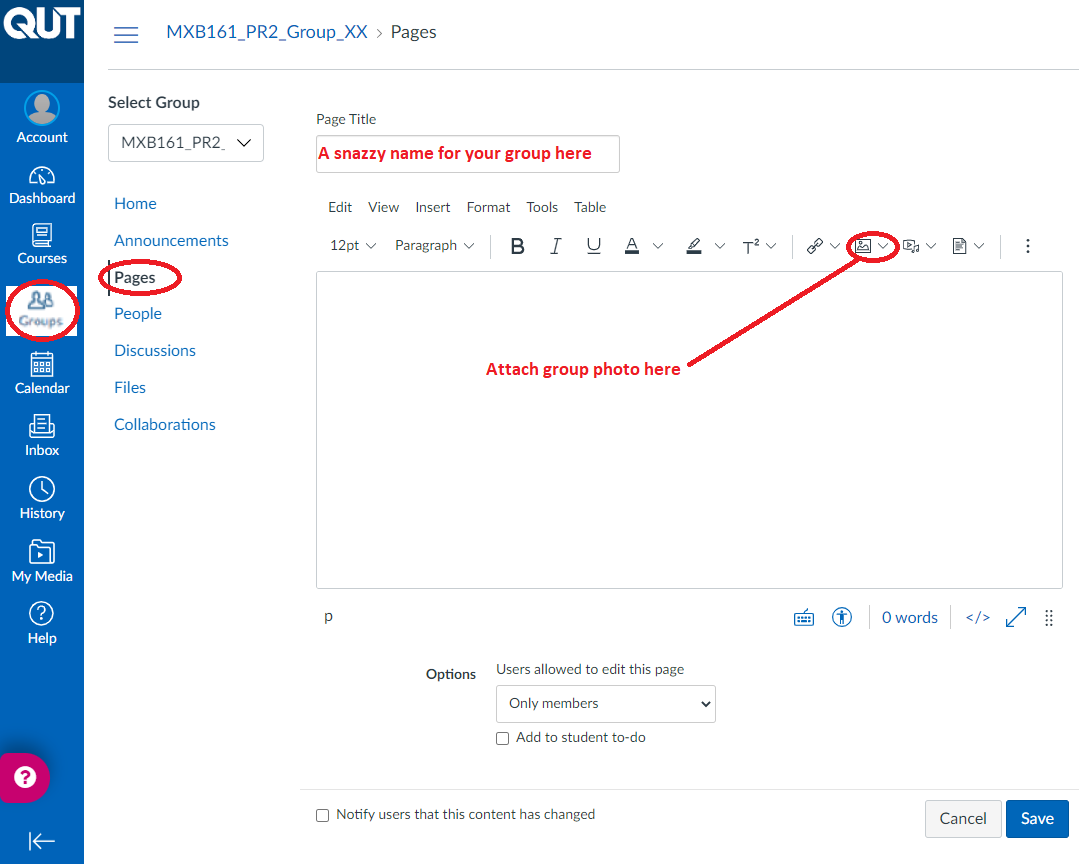

This group site is where you share files with your group members, send email, start discussions, etc. from this page.  Or, you may prefer to share information amongst the group in another way (OneDrive, GitHub, other online services, whatever).  Discuss now in your group what mechanisms you will use to share the data you create in these practicals.  You are responsible for managing this aspect of your group collaboration, so choose a mechanism that everyone is comfortable with.  Document it below.

How will your group share the data you create in the practicals?

## 1.2 Obtaining latitude and longitude from Google Maps

In this worksheet we will use Google Maps to obtain the latitude and longitude of several locations around Brisbane and measure the distance between the locations. Firstly, we will find the latitude and longitude of QUT Gardens Point. This can be obtained by searching "QUT - Gardens Point campus" at [maps.google.com.au](http://maps.google.com.au). Google Maps should navigate you to a location similar to the one shown below.

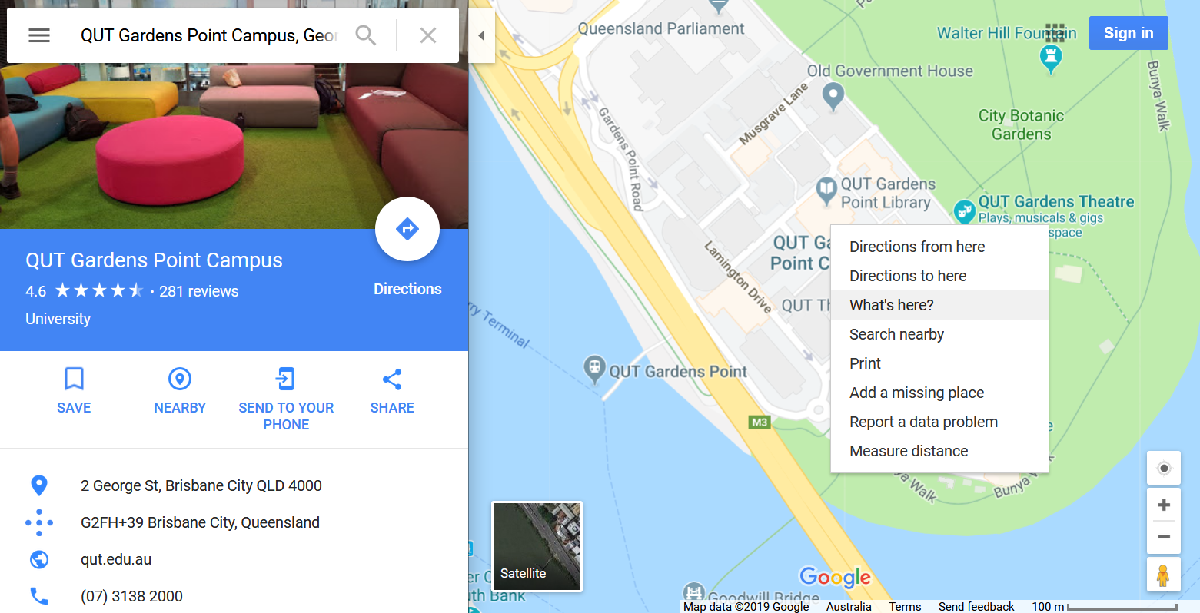

**If you're on-campus, make sure you are ****logged in**** to QUT internet access.  If you're not logged in, this next step may not work even though the map appears to have loaded correctly.**

The latitude and longitude for a location can be obtained by right clicking and choosing "What's here?".

The latitude and longitude will be shown underneath the search box. Rather than simply reveal the answer here, we'll note that for QUT *Kelvin Grove*, which is about 10 minutes up the road, the latitude is -27.451351 and the longitude is 153.016534. 

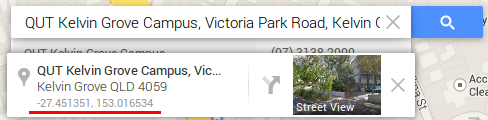

Enter the latitude and longitude for QUT Gardens Point below.

QUT_latitude  = 0  % replace with real value
QUT_longitude = 0  % replace with real value

## 1.3 The distance you travel to QUT

Now we'll compute the distance that each of you would need to travel to QUT "as the crow flies" (i.e. ignoring things like roads and rivers.) Obtain the latitude and longitude of each group member's home suburb (it doesn't have to be your actual street, just anywhere in your suburb will do) and enter this information into the box below. 

home_latitudes  = [ ]   % enter latitudes  as a list, e.g. [ -27.451351, -27.464799, etc. ]
home_longitudes = [ ]   % enter longitudes as a list, e.g. [ 153.016534, 153.009561, etc. ]
home_names = []         % enter names as a double-quoted strings, e.g. ["anne", "bob", etc.]

To calculate distances using these data, we need to think a little about the Earth. Now, the Earth is not spherical, but it's a reasonable approximation for our application to suppose that it is, with radius of 6373.6 km. Assign this value for the radius of the Earth to the variable `radius`.

If you're not familiar with it already, look up the term "great circle" online.  Now find yourself a nice figure of the globe.  Convince yourself that lines of constant *longitude* correspond to great circles, but that lines of constant *latitude* correspond to circles of smaller radius near the poles than near the equator.

Using the Earth radius above, calculate the circumference of a great circle on the Earth.

Since a full revolution around a circle is 360 degrees, calculate the number of kilometres equivalent to 1 degree on a great circle.  Call your variable `km_per_degree_latitude``.`

Convince yourselves that this is a sensible value for the distance in kilometres corresponding to a 1 degree change in *latitude*.

The distance corresponding to a 1 degree change in *longitude* depends on where you are on the Earth (it's more near the equator, and less near the poles). This relationship is captured with the formula 

`km_per_degree_longitude = km_per_degree_latitude * cos(phi)`

where `phi` is the latitude at which the calculation is made. Provided we stay in and around Brisbane for this exercise, we can simply use the latitude `phi` = -27.5 degrees.

Use the formula above to compute the distance in kilometres corresponding to a 1 degree change in longitude in Brisbane.  You will need to convert `phi` to radians to use MATLAB's `cos` function (look up how online if you forget).

It's always important to sanity-check your results.  Think of a quick check could you do to make sure your calculated distance per degree longitude is sensible.  What did you think of?

Now we can convert every student's home into (`x``,``y`) coordinates, using QUT as the origin.  To do this, subtract the latitude and longitude of QUT from those of every student's home. These represent the degree changes in latitude and longitude to get from QUT to home.  Multiply these degree changes by the appropriate scaling factors to convert them to kilometres.  These are your new (`x``,``y`) coordinates.

% longitude is the x coordinate i.e. east/west coordinate
home_x = (home_longitudes - QUT_longitude) * km_per_degree_longitude

% latitude  is the y coordinate i.e. north/south coordinate
home_y = (home_latitudes  - QUT_latitude)  * km_per_degree_latitude

For example, if the $(x,y)$ coordinates for one home are (-3.7, 1.5), that means the home is 3.7 km west of QUT, and 1.5 km north.

The *distances* of your homes from QUT, can be computed from the (`x``,``y`) coordinates using the distance formula (from the Pythagorean Theorem):

`distance = `$\sqrt{x^2 + y^2}$

Use this formula to compute the distance for all your homes.  This can be done with a single command, remembering to use the `.^` operator to compute the powers since you're operating on arrays.

distance = 0  % replace with the correct formula for the distance

Who lives the closest to QUT?  Who lives the furthest?

Plot the (`x``,``y`) coordinates of all members' homes using  circles (`'o'`). Use a star (`'*'`) to represent QUT Gardens Point (the origin) on the figure.  Enter the command(s) to create the figure.  Be sure to set `axis equal` so the distances come out looking right.

Compare this "map" that you've just created with the real Google map.  Does it look about right?  Are your homes all in the right place?  If not, go back and fix up anything that you got wrong.  Look out for typos when entering latitudes and longitudes, especially.

Compare your computed distances to those using Google Map's "Measure distance" functionality (right click on the map to find this option).  List the Google distances and your computed distances below for each home. How closely do they agree?  List any possible sources of error that could account for any variation.

## 1.4 Anyone for a burger?

In order to celebrate the success of the group, you decide to have a barbecue at one of your homes. You decide that the group member to host the barbecue should be chosen to minimise the distance that everyone has to travel.  Either of the following two criteria could be a reasonable measure to "minimise the distance". (For simplicity, assume that no carpooling is allowed.)

1. Minimise the *total *distance that *everyone *needs to travel to arrive at the barbecue.

2. Minimise the *maximum *distance that *anyone *needs to travel to arrive at the barbecue.

Decide amongst yourselves which criterion you will use, and why.

Have a go at solving the problem "by eye", refering to the figure you made earlier, and state who you think should host the barbecue according to your criterion.

Since this problem is small, MATLAB can easily solve it too by simply enumerating all possibilities and finding the minimum.  (For larger problems this isn't practical, and an active area of research is in trying to find algorithms that can efficienctly find good solutions without trying all possibilities.)

You have been provided with two MATLAB programs: `minTotalDistance`, which determines the optimal solution using criterion 1 and `minMaxDistance`, which determines the optimal solution using criterion 2. Each of these programs require two inputs: an array of location coordinates and a string indicating which problem to solve - in this case it's the 'BBQ' problem.

For example, suppose the locations found in GW1.3 were given below for the group members Jim, Lee, Karen, Tim and Ronni.

sample_x = [0.6715   -1.2075    0.7172    1.6302    0.4889]

sample_x =     0.6715   -1.2075    0.7172    1.6302    0.4889


sample_y = [1.0347    0.7269   -0.3034    0.2939   -0.7873]

sample_y =     1.0347    0.7269   -0.3034    0.2939   -0.7873


sample_names = ["Jim", "Lee", "Karen", "Tim", "Ronni"]

sample_names = 1×5 string array
    "Jim"    "Lee"    "Karen"    "Tim"    "Ronni"

To calculate the minimum total distance, we would use the following command.

total_distance_travelled = minTotalDistance(sample_x, sample_y, sample_names, 'BBQ')

To calculate the minimum total distance, we would use the following command.

total_distance_travelled = minMaxDistance(sample_x, sample_y, sample_names, 'BBQ')

Use the appropriate command for your problem to find the optimal solution.

Who should host the barbecue, and what is the total or maximum distance travelled?  Does your answer match the one you found "by eye"?

## 1.5 Who wants a coffee?

Your group has just been assigned a new project and you decide to all meet at a coffee shop to start the discussions. Use Google Maps to find the location of a coffee shop that you think will minimise the distance everyone will have to travel to get there (again, choose either minimum total distance, or minimum maximum distance). Enter the latitude and longitude values of the coffee shop.

Put these coordinates to one side for the moment.  We'll return to this "by eye" answer shortly.

The two programs `minTotalDistance` and `minMaxDistance` can also be used to solve this problem. To find the optimum location to meet and calculate the minimum total distance, we would use the following command.

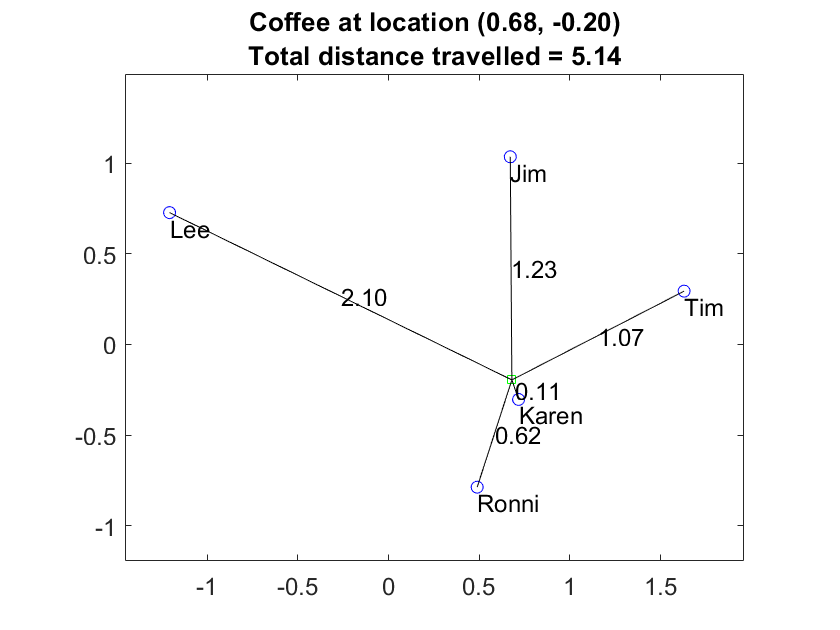

total_distance_travelled = 5.1359

x = 0.6803

y = -0.1958

[total_distance_travelled, x, y] = minTotalDistance(sample_x, sample_y, sample_names, 'coffee')

The location for coffee is returned, and also indicated on the figure by a green square.

To calculate the minimum maximum distance,

[maximum_distance_travelled, x, y] = minMaxDistance(sample_x, sample_y, sample_names, 'coffee')

Note that these programs determine the location that truly minimises the distance for everyone to travel.  Whether or not there's actually a coffee shop at this location is another story.

Use the appropriate function to find the best location for coffee, based on your chosen criteria, for your group.

Now, here's a step to make you think.  Convert the (`x``,``y`) coordinates found by the program *back to latitude and longitude coordinates* (some quick pen-and-paper algebra will reveal what formula you'll need to do this).

Identify this location on Google maps.  Is there any coffee to be found nearby?  How close is it to the place you found earlier by eye?

## 1.6 Submission

**You must submit this worksheet before the end of the practical class**. Even if the worksheet is incomplete **IT MUST BE SUBMITTED.**

So, go to the Canvas Portfolio Module and select "MXB161 - GW1: Introduction", and submit this `.mlx` file using the upload link.

Remember also to distribute copies of this worksheet, and any other files you created this week, amongst the group in the manner you've agreed upon.